function [r, el, az] = transformSatOrigin(obs_lat, obs_lon, sat_lat, sat_lon, r_sat)
    re = 6.378e6;

    r_x = r_sat - (re .* sin((pi/2)-obs_lat) .* cos(obs_lon-sat_lon));
    r_y = -re .* sin((pi/2)-obs_lat) .* sin(obs_lon-sat_lon);
    r_z = re .* cos((pi/2)-obs_lat);
    
    r = sqrt(r_x.^2 + r_y.^2 + r_z.^2);
    az = atan(r_y ./ r_x);
    el = acos(r_z ./ r);
end

function af = arrayFactor(ant_array, beta, theta, phi)
    tic;
    r_hat_x = sin(theta) .* cos(phi);
    r_hat_y = sin(theta) .* sin(phi);
    r_hat_z = cos(theta);

    [M, N] = size(ant_array);
    af = zeros(size(theta));
    for y = 0:1:N-1
        for z = 0:1:M-1
            if ant_array(z+1, y+1) > 0
                r_dot_r_hat = r_hat_y * y + r_hat_z * z;
                af = af + ant_array(z+1, y+1) * exp(-1i * (pi * r_dot_r_hat + beta));
            end
        end
    end
    af = abs(af);
    toc;
end

function af = fastArrayFactor(ant_array, exp_term)
    [M_lat, N_lon, ~] = size(exp_term);
    [M, N] = size(ant_array);
    af = zeros(M_lat, N_lon);
    tic;
    a = reshape(ant_array, 1, 1, M*N);
    af = sum(a.*exp_term);
    toc;
end

function af = newArrayFactor(ant_array, exp_term)

end

clear;
load("GAmap.mat");
r_sat = 42.400e6;
freq = 30e9;
k = 2 * pi / (3e8 / freq);
tx_power = 60;
rx_gain = 10;
N_arr = 20;

sat_lat = 0 * pi / 180;
sat_lon = -83.5* pi / 180;

bs_lat = 33 * pi / 180;
bs_lon = -83.75 * pi / 180;

[~, bs_el, bs_az] = transformSatOrigin(bs_lat, bs_lon, sat_lat, sat_lon, r_sat);

data = GA.data > 128;

lats = GA.lat * -1 * pi / 180;
lons = GA.lon * pi / 180; 

[dist, el, az] = transformSatOrigin(lats, lons, sat_lat, sat_lon, r_sat);
el = el - bs_el + pi/2;
az = az - bs_az;

array_pop = randn(N_arr, N_arr, 10) > 0.15;
scores = zeros(1, 10);

sol = zeros(N_arr);
sol_score = 0;

%r_hat_y = sin(el) .* sin(az);
%r_hat_z = cos(el);
[M_lat, N_lon] = size(el);
[M, N, ~] = size(array_pop);
[z, y] = meshgrid(0:1:M-1, 0:1:N-1);
r_hat_y = reshape(sin(el) .* sin(az), 1, M_lat * N_lon);
r_hat_z = reshape(cos(el), 1, M_lat * N_lon);
z = reshape(z, 1, M*N)';
y = reshape(y, 1, M*N)';
exp_term = exp(single(-1i) * pi * (y * r_hat_y + z * r_hat_z));
clear z;
clear y;
clear r_hat_z;
clear r_hat_y;
clear theta;
clear phi;


%a = reshape(array, 1, M*N);
%af = reshape(abs(a * exp_term), M_lat, N_lon);
clear exp_term;
%r = af;
    
% Convert spherical to Cartesian coordinates
%X = r .* sin(Theta) .* cos(Phi);
%Y = r .* sin(Theta) .* sin(Phi);
%Z = r .* cos(Theta);

% Create the spherical surface plot
%surf(X, Y, Z, r);
% Customize the plot
%title('Radiation Pattern');
%xlabel('X'); ylabel('Y'); zlabel('Z');
%axis equal;
%colormap jet;
%shading interp;


%af = @() fastArrayFactor(array, exp_term);
%af = @() arrayFactor(array, 0, Theta, Phi);
%timeit(af)

function rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, distance)
    path_loss = 20 * log10(k * distance);
    rx_power = tx_power + tx_gain + rx_gain - path_loss;
end

function plotRadiationPattern(array, N)
    [Theta, Phi] = meshgrid(linspace(pi*15/32, pi*17/32, N), linspace(-pi/32, pi/32, N));
    af = arrayFactor(array, 0, Theta, Phi);
    r = 10*log10(af);
    
    % Convert spherical to Cartesian coordinates
    X = r .* sin(Theta) .* cos(Phi);
    Y = r .* sin(Theta) .* sin(Phi);
    Z = r .* cos(Theta);
    
    % Create the spherical surface plot
    surf(X, Y, Z);
    
    % Customize the plot
    title('Radiation Pattern');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    axis equal;
    colormap jet;
    shading interp;
end

function plotMaskedHeatmap(data, mask)
    data = data .* mask;
    data = max(data - min(data(data ~= 0)), 0);
    data = data * 223 / max(data, [], "all");
    data = (data + 32) .* mask;
    imagesc(data); axis equal;
end

function new_pop = nextGeneration(pop, scores)
    mutation_q = 0.75;
    [~, ~, N] = size(pop);
    [~, idx] = sort(scores, "descend");
    pop = pop(:, :, idx);
    new_pop = pop;
    
    idx = N/2;
    for mother = 1:N/2
        for father = mother+1:N/2
            new_pop(:, :, idx) = pop(:, :, mother) | pop(:, :, father);
            %new_pop(:, :, idx) = (pop(:, :, mother) & ~pop(:, :, father)) | (~pop(:, :, mother) & pop(:, :, father));
            idx = idx + 1;
            if idx > N
                break;
            end
        end
        if idx > N
            break;
        end
    end

    mutations = randn(size(new_pop)) > mutation_q;
    new_pop = (new_pop & ~mutations) | (~new_pop & mutations);
end

clear;
load("GAmap.mat");
r_sat = 42.400e6;
freq = 30e9;
k = 2 * pi / (3e8 / freq);
tx_power = 60;
rx_gain = 10;
R_arr = 30;
C_arr = 30;

pop_sz = 20;

sat_lat = 0 * pi / 180;
sat_lon = -83.5* pi / 180;

bs_lat = 33.15 * pi / 180;
bs_lon = -83.65 * pi / 180;

[~, bs_el, bs_az] = transformSatOrigin(bs_lat, bs_lon, sat_lat, sat_lon, r_sat);

data = GA.data > 128;

lats = GA.lat * -1 * pi / 180;
lons = GA.lon * pi / 180; 

[dist, el, az] = transformSatOrigin(lats, lons, sat_lat, sat_lon, r_sat);
el = el - bs_el + pi/2;
az = az - bs_az;

array_pop = randn(R_arr, C_arr, pop_sz) > 0.15;
scores = zeros(1, pop_sz);

sol = zeros(R_arr, C_arr);
sol_score = 0;

[M_lat, N_lon] = size(el);
[M, N, ~] = size(array_pop);
[z, y] = meshgrid(0:1:M-1, 0:1:N-1);
r_hat_y = reshape(sin(el) .* sin(az), 1, M_lat * N_lon);
r_hat_z = reshape(cos(el), 1, M_lat * N_lon);
z = reshape(z, 1, M*N)';
y = reshape(y, 1, M*N)';
exp_term = exp(-1i * pi * (y * r_hat_y + z * r_hat_z));
clear z;
clear y;
clear r_hat_z;
clear r_hat_y;


%a = reshape(array, 1, M*N);
%af = reshape(abs(a * exp_term), M_lat, N_lon);
duds = 0;

for i = 1:10000
    for j = 1:pop_sz
        a = reshape(array_pop(:, :, j), 1, M*N);
        tx_gain = 20*log10(reshape(abs(a * exp_term), M_lat, N_lon));
        rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, dist);
        avg = mean2(rx_power);
        exclusion_rate = sum((rx_power < avg) .* (data < 1) , "all") / sum(data < 1, "all");
        inclusion_rate = sum((rx_power >= avg) .* data, "all") / sum(data, "all");
        scores(j) = 40*exclusion_rate + 60*inclusion_rate;
        count = j + (i-1) * pop_sz;
    end
    
    if max(scores) > sol_score
        [sol_score, idx] = max(scores)
        sol = array_pop(:, :, idx)
        duds = 0;
    else
        duds = duds + 1;
    end
    
    if (duds > 500)
        array_pop = randn(R_arr, C_arr, pop_sz) > 0.15;
        duds = 0;
    else
        array_pop = nextGeneration(array_pop, scores);
    end
end

sol_score = 87.7779

idx = 18

sol = 30×30 logical array
   0   0   1   1   0   0   0   0   0   1   1   0   0   0   0   0   1   1   0   0   0   1   1   0   1   1   0   0   1   0
   0   0   1   0   0   0   0   0   0   0   1   0   1   1   0   0   0   1   1   1   0   1   1   0   1   0   0   1   1   1
   0   0   0   0   0   0   1   1   1   0   0   1   1   1   0   0   0   1   1   0   0   0   0   0   1   0   1   1   0   1
   1   1   0   1   0   0   1   1   1   1   1   1   0   0   1   0   0   0   0   0   0   0   0   0   1   0   0   1   0   1
   0   0   1   1   1   0   0   0   0   0   0   1   0   0   0   1   1   0   0   1   1   0   0   0   1   0   0   0   1   1
   1   0   1   1   1   1   1   1   0   0   1   0   1   0   0   0   1   1   1   0   0   1   1   0   1   0   0   1   1   0
   0   0   0   1   1   0   0   0   1   1   1   0   0   1   0   1   1   0   1   1   0   0   0   1   1   0   1   0   0   1
   1   1   0   0   0   1   0   1   0   1   1   0   1   1   0   0   1   1   0   1   0   1   0   0   0   0   0   1   1   0
   0  


tx_gain = 20*log10(arrayFactor(sol, 0, el, az));

Elapsed time is 1.499107 seconds.


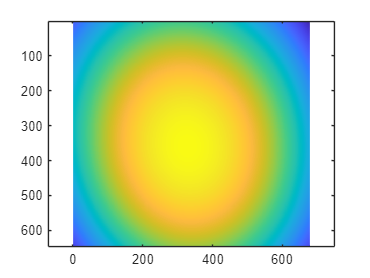

rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, dist);

imagesc(10.^(rx_power/10)); axis equal;

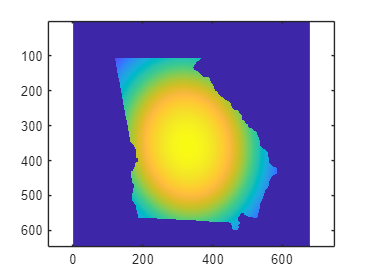


plotMaskedHeatmap(10.^(rx_power/10), data);


clear exp_term;

Elapsed time is 0.049425 seconds.


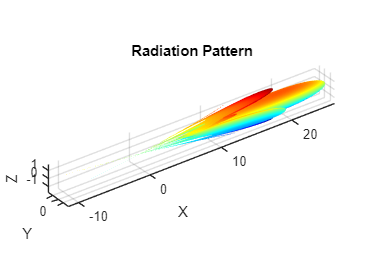

[M_lat, N_lon] = size(el);
[M, N, ~] = size(array_pop);
[z, y] = meshgrid(0:1:M-1, 0:1:N-1);
r_hat_y = reshape(sin(el) .* sin(az), 1, M_lat * N_lon);
r_hat_z = reshape(cos(el), 1, M_lat * N_lon);
z = reshape(z, 1, M*N)';
y = reshape(y, 1, M*N)';
exp_term = exp(-1i * pi * (y * r_hat_y + z * r_hat_z));
clear z;
clear y;
clear r_hat_z;
clear r_hat_y;

sol = array_pop(:,:,1);

plotRadiationPattern(sol, 100);

tx_gain = 20*log10(arrayFactor(sol, 0, el, az));

Elapsed time is 1.478812 seconds.


%tx_gain = 20*log10(arrayFactor(sol, 0, el, az));
rx_power = calcReceivePower(rx_gain, tx_gain, tx_power, k, dist);
avg = mean2(rx_power);
exclusion_rate = sum((rx_power < avg) .* (data < 1) , "all") / sum(data < 1, "all")

exclusion_rate = 0.7032

inclusion_rate = sum((rx_power >= avg) .* data, "all") / sum(data, "all")

inclusion_rate = 0.9838

40*exclusion_rate + 60*inclusion_rate

ans = 87.1579

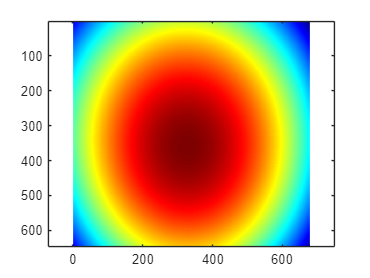

imagesc(10.^(rx_power/10)); axis equal;

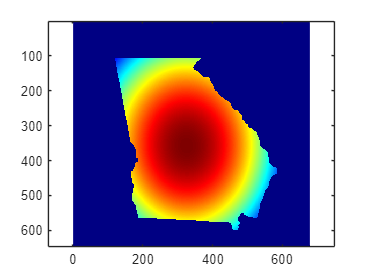


plotMaskedHeatmap(10.^(rx_power/10), data);

clear exp_term;